Use ERDDAP to retrieve the last 2 months of CTD provisional data collected at QU39

url = 'https://catalogue.hakai.org/erddap/tabledap/HakaiWaterPropertiesInstrumentProfileProvisional.csvp?&station="QU39"&time>now-2months';

options = weboptions;
options.Timeout = 120;

data = webread(url,options);

Convert some of the variables to datetime objects to make time variables on plots pretty

% Convert time to datetime object
data.time_UTC_ = datetime(data.time_UTC_,"Format","yyyy-MM-dd'T'HH:mm:ssZ",timezone="UTC");


Generate a simple scatter plot of temperature profiles at QU39

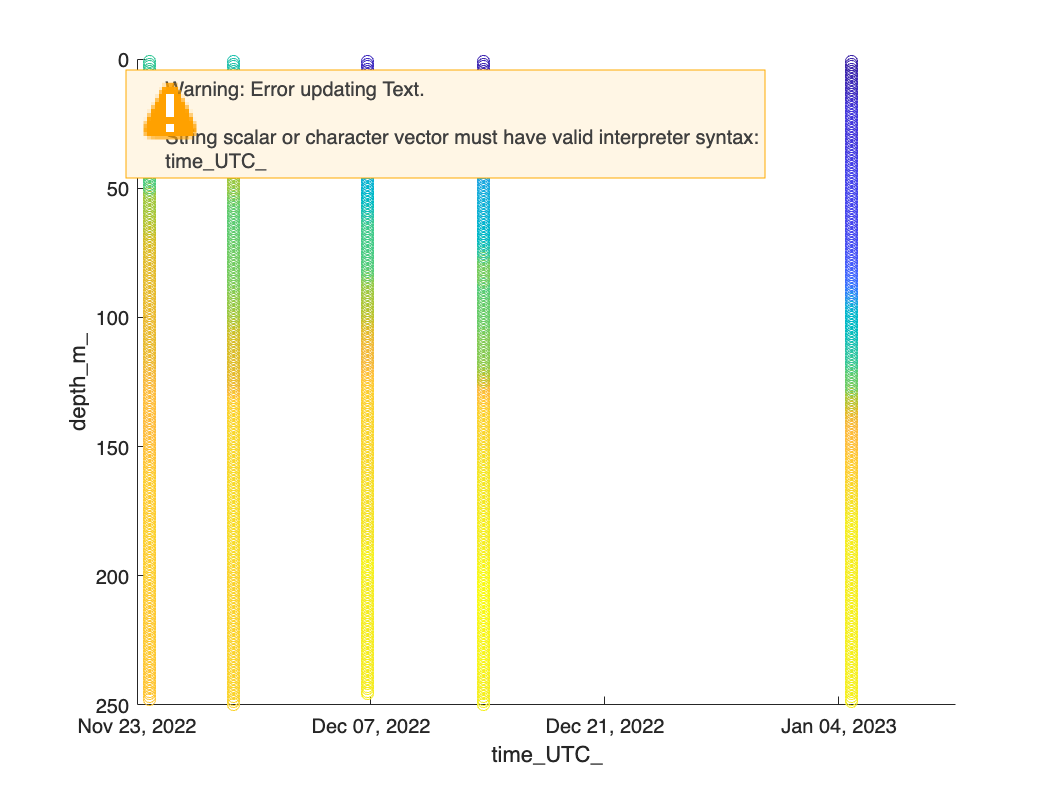

% Make a plot
scatter(data,'time_UTC_','depth_m_','ColorVariable','temperature_degree_Celsius_')
set(gca,'YDir','reverse')